# Linear Segment with Parabolic Blend (LSPB)

- suitable joint space trajectories

- has a trapezoidal velocity profile

- appropriate when a constant velocity is desired along a portion of the path

- It consists of 3 parts:

- $t_0 \to t_b :$ Quadratic polynomial and this results in a linear ramp velocity.

- At $t_b$: At the **blend time, **switch to linear function and this corresponds to constant velocity.

- $t_b \to t_f :$ The trajectory switch to quadratic polynomial so that the velocity is linear.

clear all
close all
clc

isLinspace = 1;
isTrajectory = 1;
isPlot = 1;

interpolated points of joint speed between minmum and maximum  speed intervals.

if (isLinspace)
    figure;
    n = 20;
    a = 50;
    %lower = 0.0152;
    lower = 0.0087;
    upper = 2.4053;
    temp = exp(linspace(log(1)*a, log(1.05)*a,n));
    %re-scale to be between 0 and 1
    temp_01 = temp/max(temp) - min(temp)/max(temp);
    %re-scale to be between your limits (i.e. 1 and 1.05)
    out = temp_01*(upper-lower) + lower;
    % plot(diff(out),diff(out),'o');
    plot(out,out,'o');
end

Apply linear segment with parabolic blend to generate trajectory 

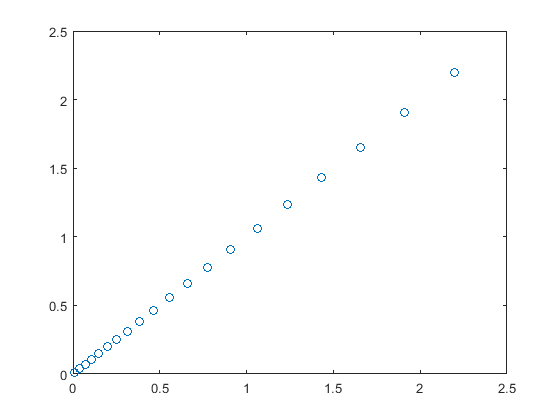

total_traj_pos = [];
total_traj_vel = [];
total_traj_acc = [];

if (isTrajectory)

    endtime = 5.0;
    constime = (endtime/2)*0.5;  
    old_amp = (endtime/2)*out(1)/2/2 + constime*out(1)/2/2;
    cnt = 1;
    for i = out
        ctr_freq = 4000;
        ctr_time = 1/ctr_freq;
        max_vel = i/ctr_freq;
%         max_vel = 1.1/4000;%i/ctr_freq;     
        endtime = 5.0;
        % 75 percent of motion is at constant velocity 
        constime = (endtime/2)*0.75;  
        % Position amplitude
        amp = (endtime/2 + constime)*max_vel*ctr_freq/2/2;
        if(0)
            if(cnt==1)
                [traj_pos, traj_vel, traj_acc] = lspb_core_modified(amp, amp,-amp,endtime,ctr_freq,max_vel);
            else
                [traj_pos, traj_vel, traj_acc] = lspb_core_modified(abs(old_amp), amp, -amp,endtime,ctr_freq,max_vel);
            end
        else
            if(cnt==1)
                [traj_pos, traj_vel, traj_acc] = lspb_core_modified(-amp, -amp,amp,endtime,ctr_freq,max_vel);
            else
                [traj_pos, traj_vel, traj_acc] = lspb_core_modified(-abs(old_amp), -amp, amp,endtime,ctr_freq,max_vel);
            end            
        end
        

        
        total_traj_pos = [total_traj_pos; traj_pos];
        total_traj_vel = [total_traj_vel; traj_vel];
        total_traj_acc = [total_traj_acc; traj_acc];
        old_amp = traj_pos(end);
        
%         [traj_pos, traj_vel, traj_acc] = lspb_core(-amp+amp_diff,-amp+amp_diff,endtime,ctr_freq,max_vel);
%         total_traj_pos = [total_traj_pos; traj_pos];
%         total_traj_vel = [total_traj_vel; traj_vel];
%         total_traj_acc = [total_traj_acc; traj_acc];
%         old_amp = traj_pos(end);
    cnt = cnt +1;   
    end
    csvwrite('trajectoryForTest/traj_pos_4.csv',total_traj_pos);
    csvwrite('trajectoryForTest/traj_vel_4.csv',total_traj_vel*ctr_freq);
    csvwrite('trajectoryForTest/traj_acc_4.csv',total_traj_acc*ctr_freq*ctr_freq);
end

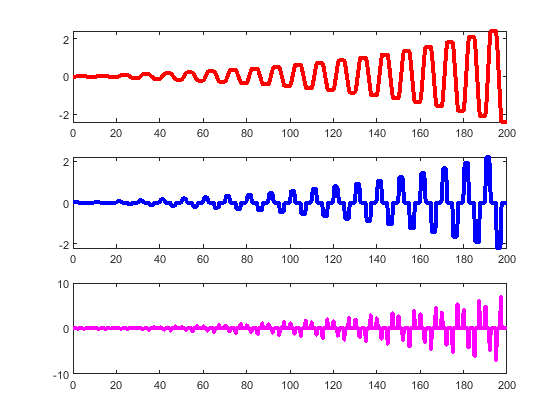

if (isPlot)
    figure;
    data_pos = load('trajectoryForTest/traj_pos_4.csv');
    data_vel = load('trajectoryForTest/traj_vel_4.csv');
    data_acc = load('trajectoryForTest/traj_acc_4.csv');

    t = 0:size(data_pos,1);
    t = t(1:end-1)/ctr_freq;
    subplot(3,1,1)
    plot(t,data_pos,'r','linewidth',3);
    subplot(3,1,2)
    plot(t,data_vel,'b','linewidth',3);
    subplot(3,1,3)
    plot(t,data_acc,'m','linewidth',3);
end